[y, Fs] = audioread("audio.wav");
player1 = audioplayer(y, Fs);
play(player1);

stop(player1);

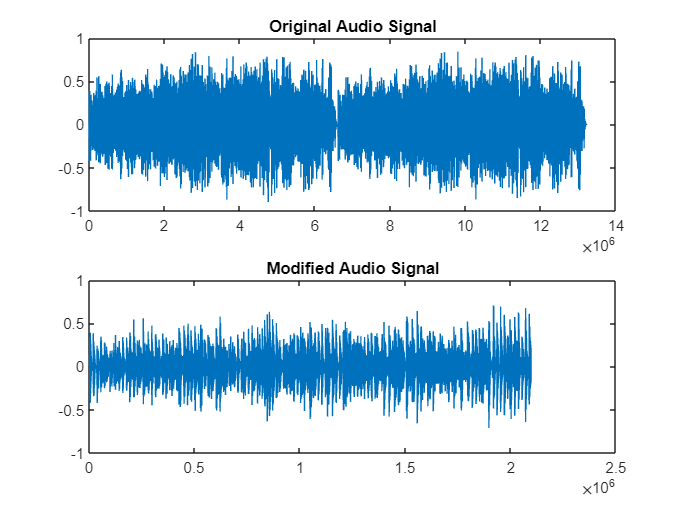

image = imread('myimage.tif');
image_gray = rgb2gray(image(:,:,1:3));
img_size = 512;
crop_range = img_size*img_size*8;
scaled = 10000;

% encryted the image by key
key = 3;
image_gray_en = encryption2D(image_gray, key);

% convert image from decimal to binary
image_gray_ext = de2bi(image_gray_en.');
% convert audio from decimal to binary
y_tmp = floor(y(1:crop_range)*scaled);
y_ext = de2bi_ext(y_tmp);

% Encode bits to LSB in audio
[l, bit] = size(y_ext);
t = 1;
for i = 1:img_size*img_size
    for j = 1:8
        y_ext(t, 1) = image_gray_ext(i, j);
        t = t + 1;
    end 
end
y_r = bi2de_ext(y_ext)/scaled;

subplot(211);
plot(y);title("Original Audio Signal");
subplot(212);
plot(y_r);title("Modified Audio Signal");

player2 = audioplayer(y_r, Fs);
%play(player2);
audiowrite("modified.wav",y_r, Fs);

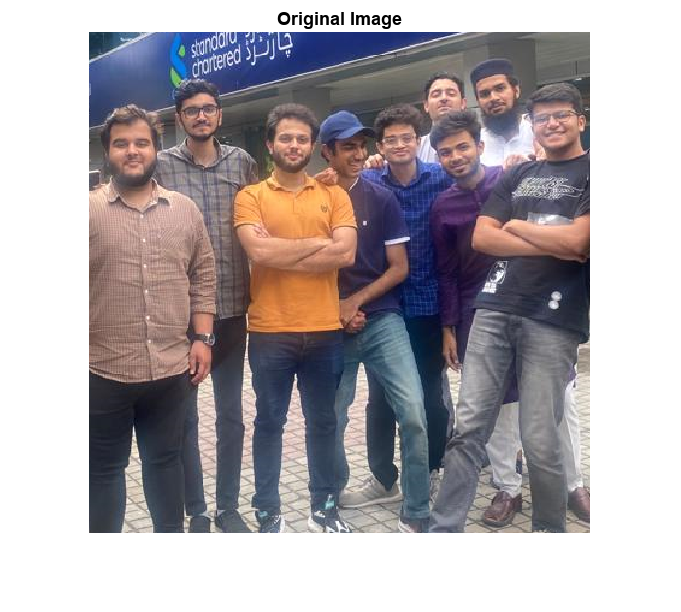

[y_r, Fs] = audioread("modified.wav");

% Decode image bits from LSB in audio
scaled = 10000;
y_test = int32(y_r*scaled);
y_test_t = de2bi_ext(y_test);

N = 512;
image_img_bin = zeros(N*N, 8);
t = 1;
for i = 1:N*N
    for j = 1:8
        image_img_bin(i, j) = y_test_t(t, 1);
        t = t + 1;
    end
end
image_img_re = bi2de(image_img_bin);
image_img_re = reshape(image_img_re, N, N).';

% decrypted using key
key = 3;
image_img_de = decryption2D(image_img_re, key);
figure;
imshow(image(:,:,1:3));title('Original Image');

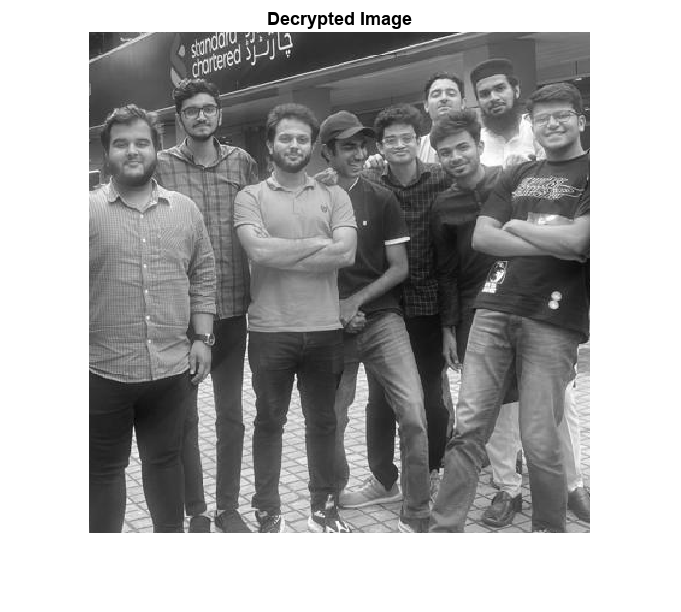

figure;
imshow(uint8(image_img_de));title('Decrypted Image');